### Importing data

ncfile = NetCDFFile('run10FinalLeticia.nc');


NetCDFFile closed.


% initialize wvt from file
wvt = WVTransform.waveVortexTransformFromFile(ncfile.path, iTime=Inf);
t = ncfile.readVariables('t');

WVTransformHydrostatic initialized from Ap, Am, A0.
NetCDFFile closed.
NetCDFFile closed.


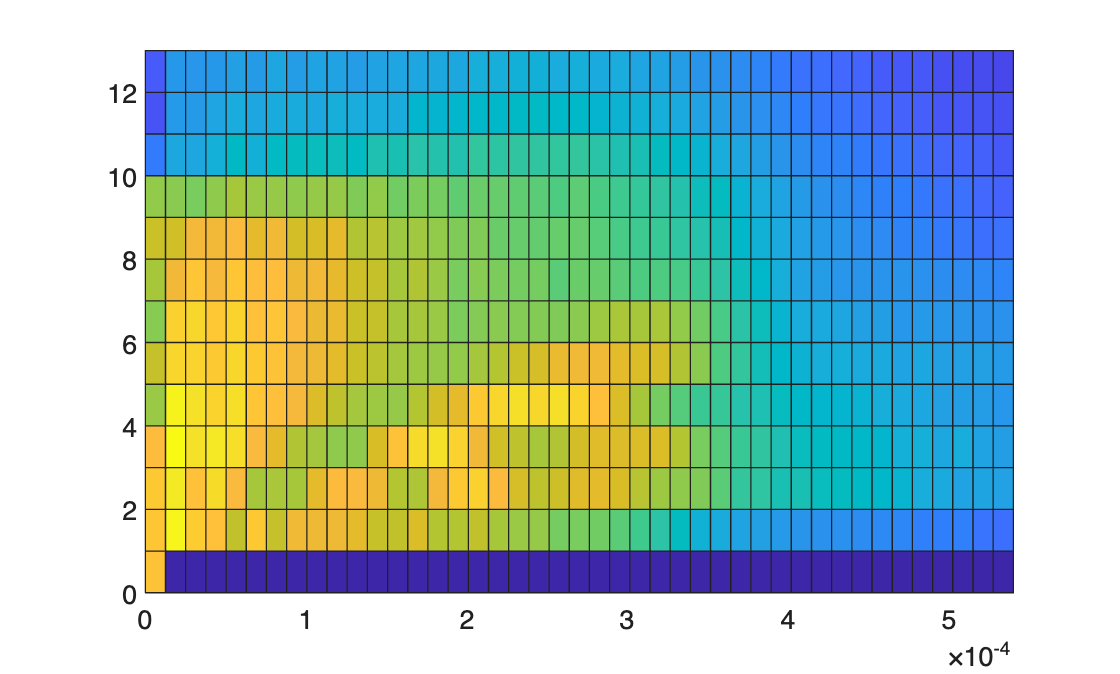

E_model= wvt.transformToRadialWavenumber( wvt.Apm_TE_factor .* (abs(wvt.Ap).^2 + abs(wvt.Am).^2) );
E_model=E_model./(wvt.kRadial(2)-wvt.kRadial(1));
j=wvt.j;
kRadial=wvt.kRadial;

figure
pcolor(kRadial,j,log10(E_model))
kIndices = kRadial<wvt.forcingWithName("adaptive damping").k_damp;
jIndices = j > 0 & j < wvt.forcingWithName("adaptive damping").j_damp;

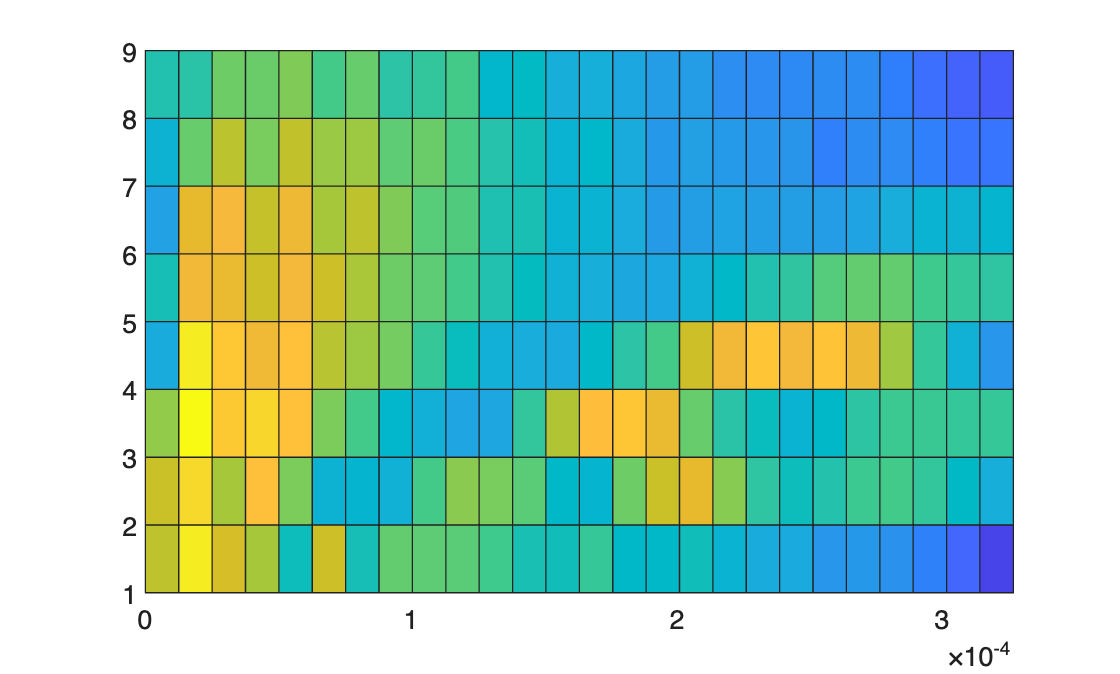

Ejk = E_model(jIndices,kIndices);
j = j(jIndices);
k = kRadial(kIndices);
pcolor(k,j,log10(Ejk))

dk = (k(2)-k(1));

sum(Ejk(:))*dk

% Ekj = Ekj.';

ans = 4.2938

# Parametrical fit

%Stratification 1 - Exponential
% f0=2*7.2921e-5*sind(latitude);
latExp=33;
L_gm = 1300;
N0 = 3*2*pi/3600;
N2funcExp = @(z) N0*N0*exp(2*z/L_gm);
LzExp=4000;
tic
igw = InternalGravityWaveSpectrum(N2funcExp,LzExp,nModes=60,nK=64,latitude=latExp);
toc

params=[3,3/2,1]; %j_star,slope,GMAmplitude
energySpectrum = igw.gmSpectrumFunctionHandle(params);

val = igw.objectiveFunction(params,k,j,Ejk)

Elapsed time is 88.287325 seconds.


fun= @(paramsGuess) igw.objectiveFunction(paramsGuess,k,j,Ejk);
tic
params_out = fminsearchbnd(fun,params,[1 1 0.1],[10 5 10])
toc


val = 1.1049e+07

%%
sum(Ejk(:)*(k(2)-k(1)))
energySpectrum = igw.gmSpectrumFunctionHandle(params_out)
energySpectrum_jk = zeros(length(j),length(k));

params_out =    10.0000    1.4170    1.8998


for indj = 1:length(j)

Elapsed time is 10.495456 seconds.


    for indk = 1:length(k)
        energySpectrum_jk(indj,indk) = energySpectrum(k(indk)+(dk/1.9),j(indj));
    end

ans = 4.2938

end

energySpectrum = function_handle with value:
    @(k,jInd)self.E_T*self.B(k,jInd)*self.M(jInd)


sum(energySpectrum_jk(:)*(k(2)-k(1)))


figure
tiledlayout(1,2)
nexttile
pcolor(k,j,log10(Ejk))
nexttile

ans = 3.6828

pcolor(k,j,log10(energySpectrum_jk))

% FMatrix=wvt.FMatrix;
% GMatrix=wvt.GMatrix;

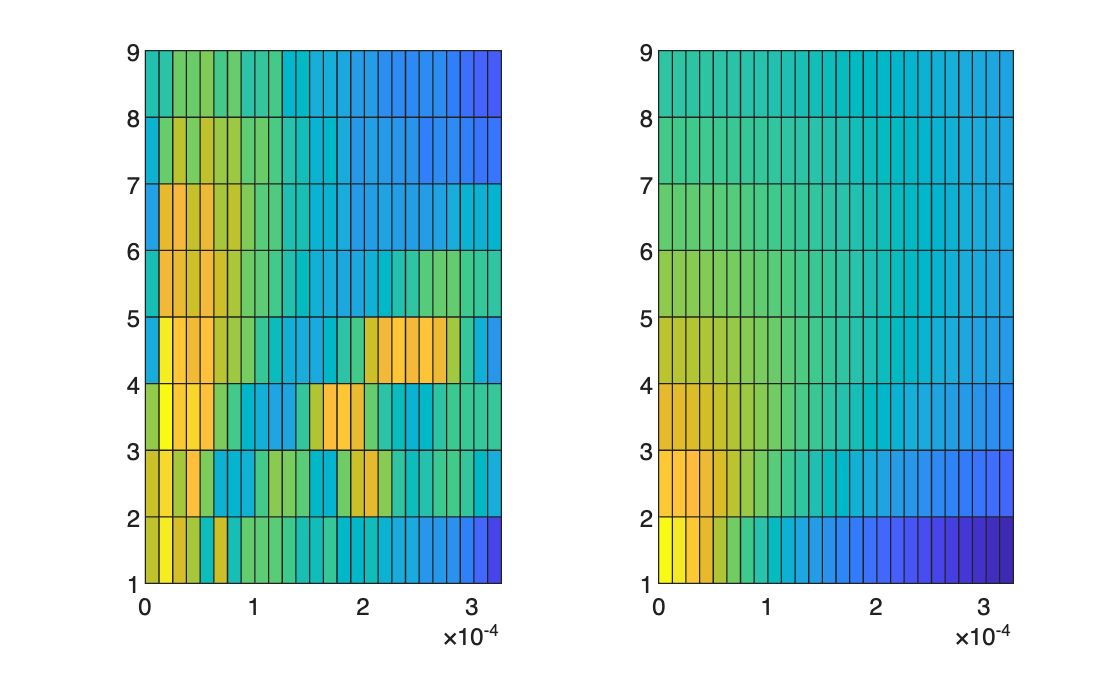

% UAm=wvt.UAm;
% UAp=wvt.UAp;
% [AmWavenumber,ApWavenumber] = wvt.transformToRadialWavenumber(UAm,UAp);
% 
% UA2= (AmWavenumber.*conj(AmWavenumber) + ApWavenumber.*conj(ApWavenumber));

% 
% Ekj = wvt.transformToRadialWavenumber( wvt.Apm_TE_factor .* (abs(wvt.Ap).^2 + abs(wvt.Am).^2) );

% u2 = zeros(14,44,22);
% 
% for jind = 1:wvt.Nj
%     F2this = FMatrix(jind,:).^2;
%     for Kind = 1:length(wvt.kRadial)
%         u2(jind,Kind,:)=UA2(jind,Kind)*F2this;
%     end
% end

% UAm=wvt.UAm;
% UAp=wvt.UAp;
% [AmWavenumber,ApWavenumber] = wvt.transformToRadialWavenumber(UAm,UAp);
% 
% UA2= (AmWavenumber.*conj(AmWavenumber) + ApWavenumber.*conj(ApWavenumber));

% u2 = zeros(14,44,22);
% 
% for jind = 1:wvt.Nj
%     F2this = FMatrix(jind,:).^2;
%     for Kind = 1:length(wvt.kRadial)
%         u2(jind,Kind,:)=UA2(jind,Kind)*F2this;
%     end
% end

% VAm=wvt.VAm;
% VAp=wvt.VAp;
% [AmWavenumber,ApWavenumber] = wvt.transformToRadialWavenumber(VAm,VAp);
% 
% VA2= (AmWavenumber.*conj(AmWavenumber) + ApWavenumber.*conj(ApWavenumber));

% v2 = zeros(14,44,22);
% 
% for jind = 1:wvt.Nj
%     F2this = FMatrix(jind,:).^2;
%     for Kind = 1:length(wvt.kRadial)
%         v2(jind,Kind,:)=VA2(jind,Kind)*F2this;
%     end
% end

% u2v2=u2+v2;
% uvVariance=squeeze(sum(sum(u2v2)));
% 
% %uvVarianceInterp=
% plot(flipup(uvVariance),wvt.z)

% u2=(wvt.u).^2;
% v2=(wvt.v).^2;
% 
% u2Mean=squeeze(mean(mean(u2,1),2));
% v2Mean=squeeze(mean(mean(v2,1),2));
% 
% HVVariance =u2Mean + v2Mean;

% plot(HVVariance,wvt.z);
% Ekj = wvt.transformToRadialWavenumber( wvt.Apm_TE_factor .* (abs(wvt.Ap).^2 + abs(wvt.Am).^2) );